clc
clear all
close all
rng(0)

# M3C Simulation

## Parameters

Simulation and control steps

Tf = 0.2;       % Total simulation time
Ts = 100e-6;    % Shortest sampling time (fastest)
Ns = Tf/Ts      % Number of sampling steps

Ns = 2000

Ti = 10e-6;	    % Integration step
Ni = Ts/Ti      % Number of integration steps between each ISR (Interrupt Service Routine)

Ni = 10

Tsim = linspace(0, Tf, Ni);

% Vxy_max = Ax+Ay;     % Branch voltage

## External system

Input internal voltage

Ax0 = 7000;
fx0 = 50;
wx0 = 2*pi*fx0;

Output internal voltage

Ay0 = 5000;
fy0 = 50;
wy0 = 2*pi*fy0;

## Modular Multilevel Matrix Converter

M3C

specsM3C = struct();

% Constants
specsM3C.Constants.Ti  = Ti;       % Integration step
specsM3C.Constants.R   = 1e-3;     % Branch resistance
specsM3C.Constants.L   = 20e-3;    % Branch inductance
specsM3C.Constants.Csm = 5e-3;    % Submodule capacitance
specsM3C.Constants.Nsm = 4;        % Submodules per cluster
specsM3C.Constants.Rx  = 0.1e-3;   % Input grid resistance
specsM3C.Constants.Lx  = 1e-3;     % Input grid inductance
specsM3C.Constants.Ry  = 0.1e-3;   % Output grid resistance
specsM3C.Constants.Ly  = 1e-3;     % Output grid inductance

% Initial Values
specsM3C.InitialValues.is = zeros(9, 1);                    % Cluster current
specsM3C.InitialValues.vc = 1.5 * (Ax0 + Ay0) * ones(9, 1); % Cluster capacitor voltage

M3C = ClassM3C_Grid(specsM3C)

M3C =   ClassM3C_Grid with properties:

        A: [6×9 double]
    pinvA: [9×6 double]
        m: 9
        N: [9×4 double]
        n: 4
    pinvN: [4×9 double]
       Ti: 1.0000e-05
        R: 1.0000e-03
        L: 0.0200
      Csm: 0.0050
      Nsm: 4
        C: 0.0013
       Rx: 1.0000e-04
       Lx: 1.0000e-03
       Ry: 1.0000e-04
       Ly: 1.0000e-03
       As: [9×9 double]
       Bs: [9×9 double]
       Es: [9×9 double]
       Ad: [9×9 double]
       Bd: [9×9 double]
       Ed: [9×9 double]
      ixy: [6×1 double]
       is: [9×1 double]
       iB: [9×1 double]
       iz: [9×1 double]
       ie: [4×1 double]
       vc: [9×1 double]
       Ec: [9×1 double]

## Phase Locked Loop

Input and output PLL

specsPLL.Ts = Ts;
xi_pll = 1/sqrt(2);
wc_pll = 50*2*pi;
specsPLL.kp = 2*xi_pll*wc_pll

specsPLL = struct with fields:
    Ts: 1.0000e-04
    kp: 444.2883

specsPLL.ki = wc_pll^2

specsPLL = struct with fields:
    Ts: 1.0000e-04
    kp: 444.2883
    ki: 9.8696e+04

specsPLL.u_min = -Inf;
specsPLL.u_max = Inf;

PLLx = ClassPLL(specsPLL)

PLLx =   ClassPLL with properties:

        g: 0
        w: 0
       Ts: 1.0000e-04
       kp: 444.2883
       ki: 9.8696e+04
       b0: -439.3535
       b1: 449.2231
       a0: -1
       a1: 1
      e_t: 0
    e_t_1: 0
      u_t: 0
    u_t_1: 0

PLLy = ClassPLL(specsPLL)

PLLy =   ClassPLL with properties:

        g: 0
        w: 0
       Ts: 1.0000e-04
       kp: 444.2883
       ki: 9.8696e+04
       b0: -439.3535
       b1: 449.2231
       a0: -1
       a1: 1
      e_t: 0
    e_t_1: 0
      u_t: 0
    u_t_1: 0

[ImperixPLL](https://imperix.com/doc/implementation/synchronous-reference-frame-pll)

## TEB PI and Filter design

% %%% Hand tuned
% kp_pi = 5;
% wn_filt = 2*pi*20;
% ki_pi = 10;

% (Mean energy)/(Input current) transfer function
vc_mean_ref = 1.5 * (Ax0 + Ay0);
k_teb = Ax0/(6*vc_mean_ref) / M3C.C

k_teb = 51.8519

G_teb = k_teb*tf(1, [1, 0])


G_teb =
 
  51.85
  -----
    s
 
Continuous-time transfer function.
Model Properties



% %% JOINT PI controller and feedback filter design
% % Pole assignment (three first order)
% % First order pole
% wn_acl = 2*pi*15;        % Natural frequency
% 
% % PI
% kp_pi = wn_acl/k_teb
% ki_pi = wn_acl^2/(3*k_teb)
% % Filter
% wn_filt = 3*wn_acl

%% JOINT PI controller and feedback filter design
% Pole assignment (one second order + one first order)
% Second order pole
xi_acl = 1;                 % Damping factor
wn_acl = 2*pi*20;           % Natural frequency
% First order pole
alpha_acl = 2*pi*20;        % Natural frequency

% PI
kp_pi = wn_acl*(wn_acl+2*xi_acl*alpha_acl)/(k_teb*(2*wn_acl*xi_acl+alpha_acl))

kp_pi = 2.4235

ki_pi = wn_acl^2*alpha_acl/(k_teb*(2*wn_acl*xi_acl+alpha_acl))

ki_pi = 101.5159

% Filter
wn_filt = 2*wn_acl*xi_acl+alpha_acl

wn_filt = 376.9911

## Low Pass Mean Energy Filter

LPF

specsLPF = struct();
specsLPF.Ts = Ts;
specsLPF.wn = wn_filt;
specsLPF.y0 = mean(M3C.vc);

LPF = ClassLPF(specsLPF)

LPF =   ClassLPF with properties:

        Ts: 1.0000e-04
        wn: 376.9911
        b0: 0.0377
        b1: 0.0377
        a0: -1.9623
        a1: 2.0377
       y_t: 18000
     y_t_1: 18000
      yf_t: 18000
    yf_t_1: 18000

## Total Energy Balance Proportional Integral Controller

PI

ix_max = 200; % Maximum input current

specsPI.Ts = Ts;
specsPI.kp = kp_pi;
specsPI.ki = ki_pi;
specsPI.u_min = -ix_max;
specsPI.u_max = ix_max;

PI = ClassPI(specsPI)

PI =   ClassPI with properties:

       Ts: 1.0000e-04
       kp: 2.4235
       ki: 101.5159
       b0: -2.4184
       b1: 2.4286
       a0: -1
       a1: 1
      e_t: 0
    e_t_1: 0
      u_t: 0
    u_t_1: 0

## Cluster Energy Model Predictive Controller

CEMPC

specsM3C.Constants.Ti = Ts;

specsCEMPC.M3C = ClassM3C(specsM3C);
specsCEMPC.is_max = 250;
specsCEMPC.vo_max = (Ax0 + Ay0)/2;
specsCEMPC.Ts = Ts;
specsCEMPC.lambda_z = 2;
specsCEMPC.lambda_o = 0.1;
specsCEMPC.lmax = 10;
specsCEMPC.Np = 1;

CEMPC = ClassCEMPC(specsCEMPC)

CEMPC =   ClassCEMPC with properties:

           M3C: [1×1 ClassM3C]
        is_max: 250
        vo_max: 6000
            Ts: 1.0000e-04
      lambda_z: 2
      lambda_o: 0.1000
          lmax: 10
            Np: 1
            NN: [9×4 double]
     options_i: [1×1 mpcActiveSetOptions]
     options_v: [1×1 mpcActiveSetOptions]
        ie_ref: [4×1 double]
        iz_ref: [9×1 double]
        vo_ref: 0
           iAi: [18×1 logical]
           iAv: [2×1 logical]
    exitflag_i: -9999
    exitflag_v: -9999

## Cluster Current Model Predictive Controller

CCMPC

specsM3C.Constants.Ti = Ts;

specsCCMPC.M3C = ClassM3C(specsM3C);
CCMPC = ClassCCMPC(specsCCMPC)

CCMPC =   ClassCCMPC with properties:

         M3C: [1×1 ClassM3C]
      lambda: 5.0000e-05
     options: [1×1 mpcActiveSetOptions]
          iA: [18×1 logical]
          vs: [9×1 double]
    exitflag: -9999

## Utils

abc to dq frame of reference

Tabc2dq = @(g) (2/3)*[cos(g), cos(g-2*pi/3), cos(g+2*pi/3); -sin(g), -sin(g-2*pi/3), -sin(g+2*pi/3)];

alpha beta to abc frame of reference and vice versa

Tabc2ab = (2/3)*[1, -1/2, -1/2; 0, sqrt(3)/2, -sqrt(3)/2];
Tab2abc = [1, 0; -1/2, sqrt(3)/2; -1/2, -sqrt(3)/2];

Rotation matrices

% Counter clockwise rotation matrix
rot = @(theta) [cos(theta), -sin(theta);
                sin(theta),  cos(theta)];

% Input
theta = wx0 * Ts;
angles = (0:specsCEMPC.Np-1) * theta;
cos_vals = cos(angles);
sin_vals = sin(angles);
ROTx = reshape([cos_vals; -sin_vals; sin_vals; cos_vals], 2, 2*specsCEMPC.Np)';

% Output
theta = wy0 * Ts;
angles = (0:specsCEMPC.Np-1) * theta;
cos_vals = cos(angles);
sin_vals = sin(angles);
ROTy = reshape([cos_vals; -sin_vals; sin_vals; cos_vals], 2, 2*specsCEMPC.Np)';

% DISCLAIMER: This rotation matrices produce a vector of Np steps starting
% from now, so it actually only predicts Np-1 steps. This has to be taken in
% account in case of control delay compensation.

# Simulation

Buffer

% Initialize
buffer                      = struct();

% Constants
buffer.Ts                   = Ts;                           % Control sample time

% Variables
buffer.is                   = zeros(M3C.m, Ns);             % Cluster current
buffer.ixy                  = zeros(size(M3C.A, 1), Ns);    % External current
buffer.iB                   = zeros(M3C.m, Ns);             % Basic current
buffer.iz                   = zeros(M3C.m, Ns);             % Circulating current
buffer.ie                   = zeros(M3C.n, Ns);             % L.I. circulating current
buffer.vs                   = zeros(M3C.m, Ns);             % Cluster voltage
buffer.vxy                  = zeros(size(M3C.A, 1), Ns);    % External voltage
buffer.vB                   = zeros(M3C.m, Ns);             % Basic voltage
buffer.vo                   = zeros(1, Ns);                 % Common mode voltage
buffer.Ec                   = zeros(M3C.m, Ns);             % Cluster capacitor energy (one-step lookahead)
buffer.vc                   = zeros(M3C.m, Ns);             % Cluster capacitor voltage
buffer.Ec_mean              = zeros(1, Ns);                 % Predicted mean cluster capacitor energy
buffer.Ec_mean_filt         = zeros(1, Ns);                 % Predicted filtered mean cluster capacitor energy
buffer.vc_mean              = zeros(1, Ns);                 % Predicted mean cluster capacitor energy
buffer.vc_mean_filt         = zeros(1, Ns);                 % Predicted filtered mean cluster capacitor voltage

buffer.u_TEB                = zeros(1, Ns);                 % TEB PI control action

buffer.gx                   = zeros(1, Ns);                 % Input voltage angle
buffer.wx                   = zeros(1, Ns);                 % Input voltage frequency
buffer.gy                   = zeros(1, Ns);                 % Output voltage angle
buffer.wy                   = zeros(1, Ns);                 % Output voltage frequency

buffer.gx_pll               = zeros(1, Ns);                 % PLL estimation of input voltage angle
buffer.wx_pll               = zeros(1, Ns);                 % PLL estimation of input voltage frequency
buffer.gy_pll               = zeros(1, Ns);                 % PLL estimation of output voltage angle
buffer.wy_pll               = zeros(1, Ns);                 % PLL estimation of output voltage frequency

buffer.ex_pll               = zeros(1, Ns);                 % Input PLL error
buffer.ux_pll               = zeros(1, Ns);                 % Input PLL control action
buffer.ey_pll               = zeros(1, Ns);                 % Output PLL error
buffer.uy_pll               = zeros(1, Ns);                 % Output PLL control action

buffer.is_ref               = zeros(M3C.m, Ns);
buffer.ixy_ref              = zeros(size(M3C.A, 1), Ns);
buffer.iB_ref               = zeros(M3C.m, Ns);
buffer.iz_ref               = zeros(M3C.m, Ns);
buffer.ie_ref               = zeros(M3C.n, Ns);

Initialize

Ax = Ax0;
Ay = Ay0;
wx = wx0;
wy = wy0;
gx = 0;
gy = 0;

vxa = Ax * cos(gx);
vxb = Ax * cos(gx-2*pi/3);
vxc = Ax * cos(gx+2*pi/3);
vyr = Ay * cos(gy);
vys = Ay * cos(gy-2*pi/3);
vyt = Ay * cos(gy+2*pi/3);
vxy = [vxa; vxb; vxc; vyr; vys; vyt];

vc_mean_ref = 1.5 * (Ax + Ay);
Ec_mean_ref = M3C.C/2 * vc_mean_ref^2;

vc_ref = vc_mean_ref * ones(9, 1);
Ec_ref = Ec_mean_ref * ones(9, 1);

Run

% Initialize progress bar
h = waitbar(0, 'Simulating...');

for ts = 1:Ns

%% Measure external voltages
vB = M3C.A' * vxy;

%% Input PLL
vxdq = Tabc2dq(PLLx.g) * vxy(1:3);
PLLx = PLLx.estimate(vxdq/norm(vxdq), 0);

%% Output PLL
vydq = Tabc2dq(PLLy.g) * vxy(4:6);
PLLy = PLLy.estimate(vydq/norm(vydq), 0);

%% "Measure" converter cluster mean voltage
Ec = M3C.Ec;
vc = sqrt(Ec * 2 / M3C.C);

Ec_mean = mean(Ec);
vc_mean = mean(vc);

%% Low pass filter for mean cluster energy
LPF = LPF.filter(vc_mean);
vc_mean_filt = LPF.yf_t;
Ec_mean_filt = M3C.C / 2 * vc_mean_filt^2;

%% Calculate input currents references (TEB PI)
% dq
PI = PI.control(vc_mean_ref, vc_mean_filt);
ixd_ref = PI.u_t;
ixq_ref = 0;
% abc
ixa_ref = ixd_ref * cos(PLLx.g)          - ixq_ref * sin(PLLx.g);
ixb_ref = ixd_ref * cos(PLLx.g - 2*pi/3) - ixq_ref * sin(PLLx.g - 2*pi/3);
ixc_ref = ixd_ref * cos(PLLx.g + 2*pi/3) - ixq_ref * sin(PLLx.g + 2*pi/3);

%% Calculate output currents references (Converter application)
% dq
iyd_ref = 100;
iyq_ref = 0;
% abc
iyr_ref = iyd_ref * cos(PLLy.g)          - iyq_ref * sin(PLLy.g);
iys_ref = iyd_ref * cos(PLLy.g - 2*pi/3) - iyq_ref * sin(PLLy.g - 2*pi/3);
iyt_ref = iyd_ref * cos(PLLy.g + 2*pi/3) - iyq_ref * sin(PLLy.g + 2*pi/3);

%% Concatenate external currents references
ixy_ref = [ixa_ref; ixb_ref; ixc_ref; iyr_ref; iys_ref; iyt_ref];

%% Basic currents references
iB_ref = M3C.pinvA * ixy_ref;

%% Predict external voltages/currents
vB_pred = predict_basic_assuming_symmetrical(vxy, specsCEMPC.Np, ROTx, ROTy, Tabc2ab, Tab2abc, M3C.pinvA);
iB_pred = predict_basic_assuming_symmetrical(M3C.ixy, specsCEMPC.Np, ROTx, ROTy, Tabc2ab, Tab2abc, M3C.pinvA);

%% Cluster energy MPC
CEMPC = CEMPC.control(Ec, vB_pred, iB_pred);

%% Cluster current MPC
is_ref = CEMPC.iz_ref + iB_ref;
CCMPC = CCMPC.control(is_ref, vc_mean_ref, M3C.is, vB, CEMPC.vo_ref);

%% Store variables
buffer.is(:, ts) = M3C.is;
buffer.ixy(:, ts) = M3C.ixy;
buffer.iB(:, ts) = M3C.iB;
buffer.iz(:, ts) = M3C.iz;
buffer.ie(:, ts) = M3C.ie;
buffer.vs(:, ts) = CCMPC.vs;
buffer.vxy(:, ts) = vxy;
buffer.vB(:, ts) = vB;
buffer.vo(:, ts) = CEMPC.vo_ref;
buffer.Ec(:, ts) = Ec;
buffer.vc(:, ts) = vc;
buffer.Ec_mean(ts) = Ec_mean;
buffer.Ec_mean_filt(ts) = Ec_mean_filt;
buffer.vc_mean(ts) = vc_mean;
buffer.vc_mean_filt(ts) = vc_mean_filt;

buffer.u_TEB(ts) = PI.u_t;

buffer.gx(ts) = gx;
buffer.wx(ts) = wx;
buffer.gy(ts) = gy;
buffer.wy(ts) = wy;

buffer.gx_pll(ts) = PLLx.g;
buffer.wx_pll(ts) = PLLx.w;
buffer.gy_pll(ts) = PLLy.g;
buffer.wy_pll(ts) = PLLy.w;

buffer.ex_pll(ts) = PLLx.e_t;
buffer.ux_pll(ts) = PLLx.u_t;
buffer.ey_pll(ts) = PLLy.e_t;
buffer.uy_pll(ts) = PLLy.u_t;

buffer.is_ref(:, ts) = is_ref;
buffer.ixy_ref(:, ts) = ixy_ref;
buffer.iB_ref(:, ts) = iB_ref;
buffer.iz_ref(:, ts) = CEMPC.iz_ref;
buffer.ie_ref(:, ts) = CEMPC.ie_ref;

%% Integrate external system and converter
for ti = 1:Ni
    % Update model
    M3C = M3C.step(CCMPC.vs, vxy, CEMPC.vo_ref);
    
    % Update external system
    gx = mod(gx + wx * Ti, 2*pi);
    gy = mod(gy + wy * Ti, 2*pi);
    vxa = Ax * cos(gx);
    vxb = Ax * cos(gx-2*pi/3);
    vxc = Ax * cos(gx+2*pi/3);
    vyr = Ay * cos(gy);
    vys = Ay * cos(gy-2*pi/3);
    vyt = Ay * cos(gy+2*pi/3);
    vxy = [vxa; vxb; vxc; vyr; vys; vyt];
end

% Update progress bar
waitbar(ts/Ns, h, sprintf('Progreso: %d%%', round((ts/Ns)*100)));

end

% Close progress bar
close(h)

# Plot

buffer = struct with fields:
              Ts: 1.0000e-04
              is: [9×2000 double]
             ixy: [6×2000 double]
              iB: [9×2000 double]
              iz: [9×2000 double]
              ie: [4×2000 double]
              vs: [9×2000 double]
             vxy: [6×2000 double]
              vB: [9×2000 double]
              vo: [0 0.0206 0.1066 0.2517 0.4232 0.5901 0.7325 0.8419 0.9174 0.9630 0.9850 0.9904 0.9855 0.9759 0.9656 0.9573 0.9528 0.9531 0.9582 0.9682 0.9826 1.0012 1.0236 1.0493 1.0781 1.1097 1.1438 1.1799 1.2173 1.2554 1.2928 … ] (1×2000 double)
              Ec: [9×2000 double]
              vc: [9×2000 double]
         Ec_mean: [202500 2.0250e+05 2.0250e+05 2.0251e+05 2.0251e+05 2.0252e+05 2.0253e+05 2.0254e+05 2.0254e+05 2.0255e+05 2.0256e+05 2.0257e+05 2.0258e+05 2.0258e+05 2.0259e+05 2.0260e+05 2.0261e+05 2.0261e+05 2.0262e+05 2.0263e+05 … ] (1×2000 double)
    Ec_mean_filt: [202500 2.0250e+05 2.0250e+05 2.0250e+05 2.0250e+05 2.0250e+05 2.0250e+05 2.02

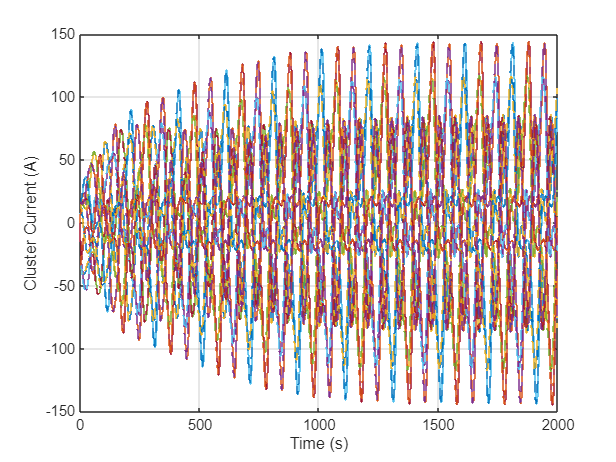

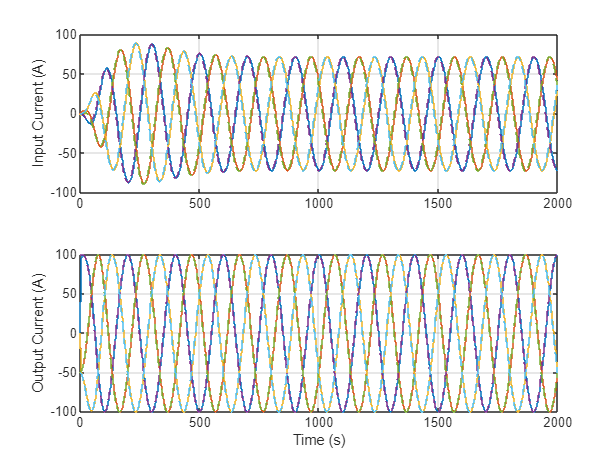

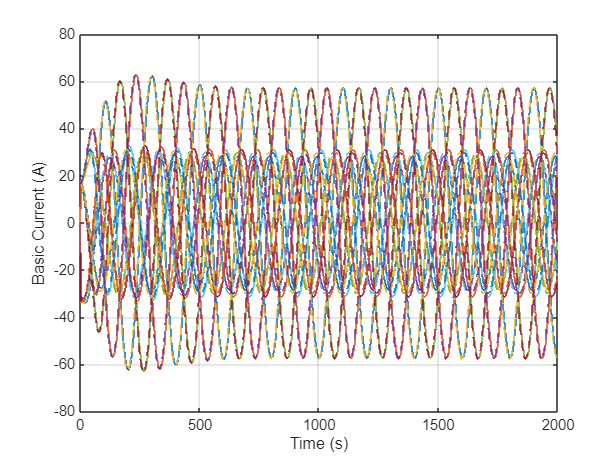

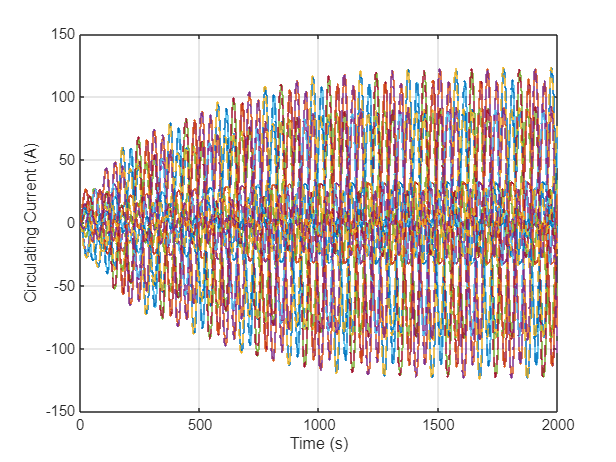

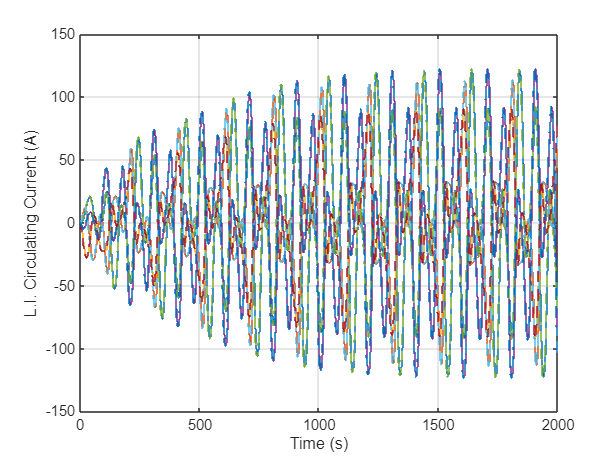

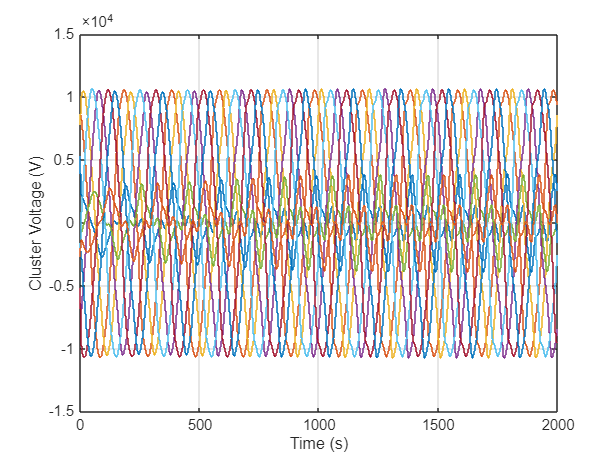

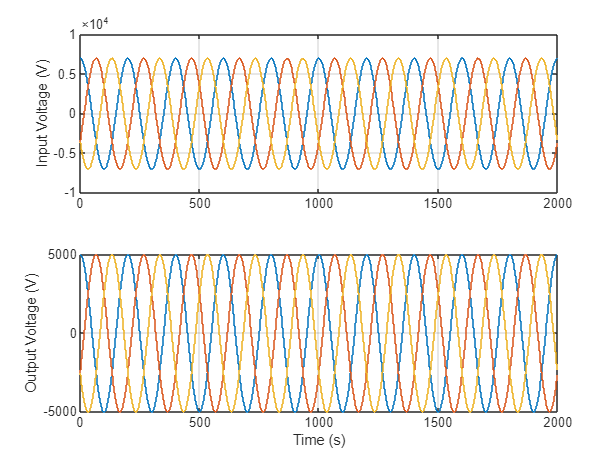

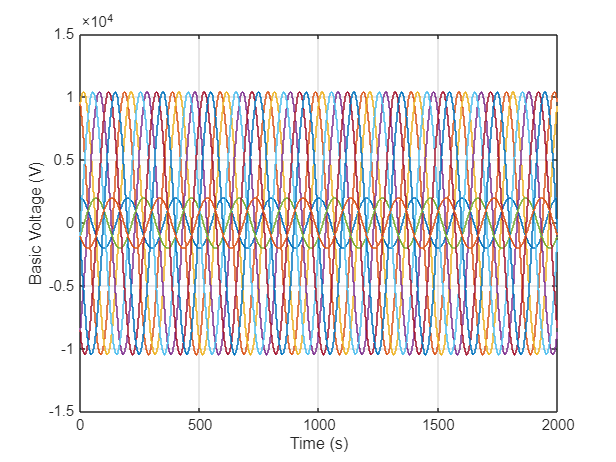

run("Plot.mlx")